New RANSAC

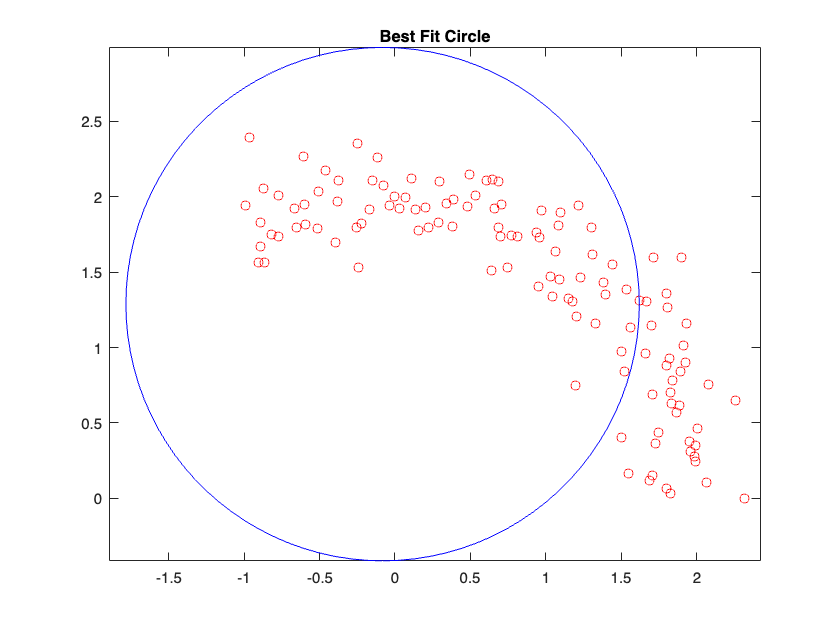

% Parameters
num_iterations = 10000; % Max number of RANSAC iterations
true_rad = 2; % True radius of the generated circle

% TODO: REMOVE THIS COMMENT WHEN DONE
% For the next two parameters, I have found that they should be adjusted
% together. When radius tolerance goes down, the circle becomes more of the
% right size but is a little more off. I think this ratio works best from
% the few graphs I generated, but its all just guesses

tolerance = true_rad/2; % Distance tolerance to consider a point an inlier
radius_tolerance = 0.3; % Tolerance for the radius

best_inlier_count = 0;

% Generate circle data for demonstration
[x, y, rs, theta] = makeCircle(true_rad, 0, 120, 0.2);

% RANSAC Algorithm
for k = 1:num_iterations
    % Randomly select 3 unique points
    indices = randperm(size(x, 1), 3);
    pts = [x(indices), y(indices)];
    
    % Check for collinearity
    if checkCollinearity(pts(1,:), pts(2,:), pts(3,:))
        continue; % Skip this iteration if points are collinear
    end

    A = [2*pts(:,1), 2*pts(:,2), -ones(3, 1)];
    b = pts(:,1).^2 + pts(:,2).^2;
    
    % Solve for circle parameters
    w = A \ b;
    center_x = w(1);
    center_y = w(2);
    computed_radius = sqrt(center_x^2 + center_y^2 + w(3));
    
    % Count inliers
    inliers_count = 0;
    for j = 1:size(x, 1)
        dist = norm([center_x; center_y] - [x(j); y(j)]);
        if abs(dist - computed_radius) < tolerance
            inliers_count = inliers_count + 1;
        end
    end
    
    % Update best model if current model has more inliers and meets radius criteria
    if inliers_count > best_inlier_count && ...
       computed_radius > true_rad - radius_tolerance && ...
       computed_radius < true_rad + radius_tolerance
        best_inlier_count = inliers_count;
        best_center_x = center_x;
        best_center_y = center_y;
        best_computed_radius = computed_radius;
    end
end

% Plotting
clf;
th = 0:pi/50:2*pi;
xunit = best_computed_radius * cos(th) + best_center_x;
yunit = best_computed_radius * sin(th) + best_center_y;
plot(x, y, 'ro'); hold on; % Plot generated points
plot(xunit, yunit, 'b-'); % Plot best fit circle
axis equal; % Make axes equal to ensure circle does not look oval because it is so confusing and trippy
title('Best Fit Circle');

RANSAC TRY ON HOMEWORK DATA

% Load your LIDAR data
% load('hwdata','angles','positions','scans');
% Parameters for RANSAC
globalCleaned = []


globalCleaned =

     []



load('hw8sampledata.mat','angles', 'positions', 'scans');
for i=1:size(positions,1)
    th = deg2rad(angles(i));
    RobotToGlobal = [cos(th) -sin(th) positions(i,1);
                     sin(th) cos(th) positions(i,2);
                     0 0 1];
    ScannerToRobot = [1 0 -0.082;
                      0 1 0;
                      0 0 1];
    ScannerToGlobal = RobotToGlobal * ScannerToRobot;
    ranges = scans{i}.ranges;
    thetasInRadians = scans{i}.thetasInRadians;
    cart = [cos(thetasInRadians);
            sin(thetasInRadians)].*[ranges; ranges];
    cart = [cart; ones(1, size(cart,2))];
    cleaned = cart(:, ranges~=0);
    % globalCleaned = ScannerToGlobal*cleaned;
    globalCleaned = [globalCleaned ScannerToGlobal*cleaned];
    % figure;
    % title(['x=',num2str(positions(i,1)), ...
    %         ' y=', num2str(positions(i,2)),...
    %         ' angles=', num2str(angles(i))]);
    % scatter(globalCleaned(1,:), globalCleaned(2,:), 'b.');
    % axis("equal");
    % figure(f);
    % hold on;
    % scatter(globalCleaned(1,:), globalCleaned(2,:), 'b.');
    % axis("equal");
end
old_x = globalCleaned(1,:)';
old_y = globalCleaned(2,:)';

num_iterations = 70000; % Max number of RANSAC iterations
true_rad = .131; % True radius of the generated circle
tolerance = true_rad/10; % Distance tolerance to consider a point an inlier
radius_tolerance = 0.005; % Tolerance for the radius
[best_center_x, best_center_y, best_computed_radius, best_inlier_count] = ransacForCircle(x,y,num_iterations, true_rad, tolerance, radius_tolerance)

best_center_x = 1.4007

best_center_y = 1.5439

best_computed_radius = 0.1343

best_inlier_count = 5

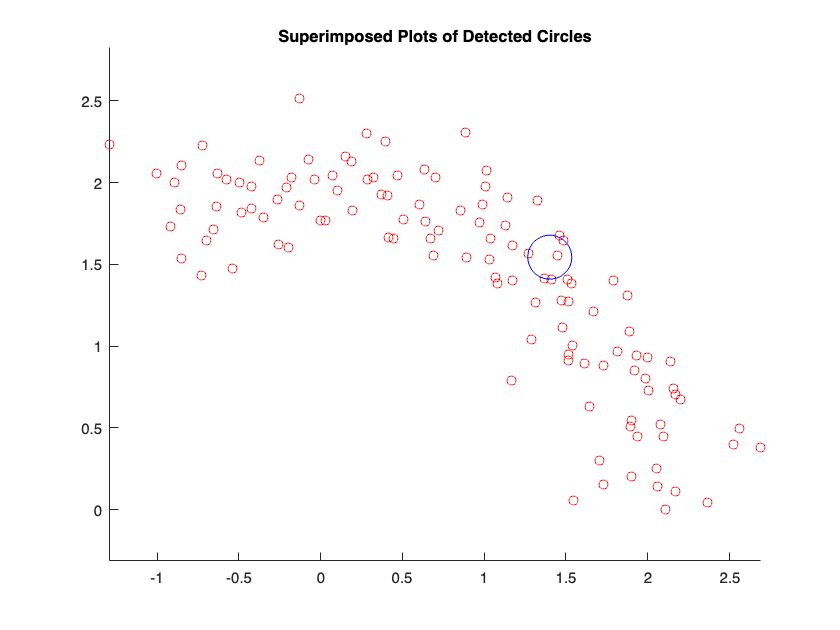

% Initialize the superimposed figure
clf;
figure;
hold on;
axis equal;
title('Superimposed Plots of Detected Circles');


% % Process each scan
% for i = 1:length(scans)
%     scanData = scans{i};
%     anglesInRadians = deg2rad(scanData.thetas); % Assuming thetas are stored in degrees
%     x = scanData.ranges .* cos(anglesInRadians);
%     y = scanData.ranges .* sin(anglesInRadians);
% 
%     [best_center_x, best_center_y, best_computed_radius, best_inlier_count] = ransacForCircle(x, y, num_iterations, true_rad, tolerance, radius_tolerance);
% 
    % Plotting
    th = 0:pi/50:2*pi;
    xunit = best_computed_radius * cos(th) + best_center_x;
    yunit = best_computed_radius * sin(th) + best_center_y;
    plot(x, y, 'ro'); hold on; % Plot generated points
    plot(xunit, yunit, 'b-'); % Plot best fit circle

axis equal;
hold off;

% a = x;
% b = y;
% [x,y] = meshgrid(-1:0.01:2,-1:0.01:2);
% v = 0;
% for i=1:size(a,1)
%     dist = [(a(i, :) - best_center_x); (b(i, :) - best_center_y)];
%     if norm(dist) > true_rad
%     v = v - log(sqrt((x-a(i, :)).^2 + (y-b(i, :)).^2));
%     end
% 
% end
% for theta = 0:0.1:2*pi
% %sources have coordinates (a,b)
%         a = true_rad * cos(theta) + best_center_x;
%         b = true_rad * sin(theta) + best_center_y;
%         v = v +  2 *log(sqrt((x-a).^2 + (y-b).^2));
%     end
% [U,V] = gradient(v,1, 1);
% contour(x,y,v,10);
% q = quiver(x(1:10:end, 1:10:end),y(1:10:end, 1:10:end),U(1:10:end, 1:10:end),V(1:10:end, 1:10:end), 'ShowArrowHead','on','LineWidth',1,'MarkerSize',3);
% q.Color = 'red';

% [x,y] = meshgrid(-1:0.01:2,-1:0.01:2);
% 
% for i = 1:length(A)
%     dist = sqrt((a(i) - best_center_x)^2 + (b(i) - best_center_y)^2);
%     if dist > true_rad
%         v = v - log(sqrt((x - a(i)).^2 + (y - b(i)).^2));
%     end
% end

% for theta = 0:0.1:2*pi
%     a_circle = true_rad * cos(theta) + best_center_x;
%     b_circle = true_rad * sin(theta) + best_center_y;
%     v = v + 3 * log(sqrt((x - a_circle).^2 + (y - b_circle).^2));
% end
% 
% % Calculate gradient
% [U, V] = gradient(v, 0.01, 0.01);  
% 
% % Visualize the potential field and its gradient
% figure;
% contour(x, y, v, 40);  % Increased number of contour levels for better visibility
% hold on;
% quiver(x(1:5:end, 1:5:end), y(1:5:end, 1:5:end), U(1:5:end, 1:5:end), V(1:5:end, 1:5:end), 'r');
% hold off;
% axis equal;
% title('Potential Field and Gradient Visualization');
% xlabel('X Axis');
% ylabel('Y Axis');

grid_size = 27;

% Normalize scanned coordinates
x = round(globalCleaned(1,:) * 100);
y = round(globalCleaned(2,:) * 100);

% Convert coordinates to grid indices
x_grid = max(min(round(x * (grid_size-1) / max(x)), grid_size), 1); 
y_grid = max(min(round(y * (grid_size-1) / max(y)), grid_size), 1); 

grid = ones(grid_size, grid_size);

% Place points on the grid
for i = 1:length(x)
    grid(y_grid(i), x_grid(i)) = 0;
end

% To extract the points from the grid and convert back to the original coordinate range of -1 to 2
new_x = [];
new_y = [];
for j = 1:grid_size
    for k = 1:grid_size
        if grid(j, k) == 0
            % Convert back to normalized coordinates
            normalized_x = (k-1)/(grid_size-1);
            normalized_y = (j-1)/(grid_size-1);
            % Map normalized coordinates back to the original range [-0.5, 1.5]
            original_x = 2 * normalized_x - 0.4;  % Scale and translate
            original_y = 2 * normalized_y - 0.4;  % Scale and translate
            new_x = [new_x, original_x];
            new_y = [new_y, original_y];
        end
    end
end

% Display the new points
disp('New X Coordinates:');

New X Coordinates:


disp(new_x);

   -0.4000   -0.3231   -0.2462   -0.1692   -0.0923   -0.0154    0.0615    0.1385    0.2154    0.2923    0.3692    0.4462    0.5231    0.6000    0.6769    0.7538    0.8308    0.9077    0.9846   -0.4000    0.9077   -0.4000    0.9077    0.9846   -0.4000    0.9077    0.9846   -0.4000    0.9077   -0.4000    0.9077   -0.4000    0.7538    0.8308    0.9077   -0.4000    0.6769    0.7538   -0.4000    0.6769    0.7538   -0.4000   -0.0923    0.6769    0.7538   -0.4000   -0.3231   -0.2462   -0.1692   -0.0923    0.6769    0.7538   -0.4000   -0.3231   -0.2462   -0.1692   -0.0923    0.6769    0.7538    1.4462   -0.4000    0.6769    0.7538    1.4462    0.6769    0.7538    1.4462   -0.4000    0.6769    0.7538    1.4462   -0.4000   -0.2462   -0.1692    0.6769    0.7538    0.8308    0.9077    1.4462   -0.4000   -0.1692   -0.0923    0.6769   -0.4000   -0.1692   -0.0923    1.4462   -0.4000   -0.2462   -0.1692    1.4462    1.5231   -0.4000    1.4462    1.5231   -0.4000    1.4462    1.5231   -0.4000    1.4462

disp('New Y Coordinates:');

New Y Coordinates:


disp(new_y);

   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.3231   -0.3231   -0.2462   -0.2462   -0.2462   -0.1692   -0.1692   -0.1692   -0.0923   -0.0923   -0.0154   -0.0154    0.0615    0.0615    0.0615    0.0615    0.1385    0.1385    0.1385    0.2154    0.2154    0.2154    0.2923    0.2923    0.2923    0.2923    0.3692    0.3692    0.3692    0.3692    0.3692    0.3692    0.3692    0.4462    0.4462    0.4462    0.4462    0.4462    0.4462    0.4462    0.4462    0.5231    0.5231    0.5231    0.5231    0.6000    0.6000    0.6000    0.6769    0.6769    0.6769    0.6769    0.7538    0.7538    0.7538    0.7538    0.7538    0.7538    0.7538    0.7538    0.8308    0.8308    0.8308    0.8308    0.9077    0.9077    0.9077    0.9077    0.9846    0.9846    0.9846    0.9846    0.9846    1.0615    1.0615    1.0615    1.1385    1.1385    1.1385    1.2154    1.2154

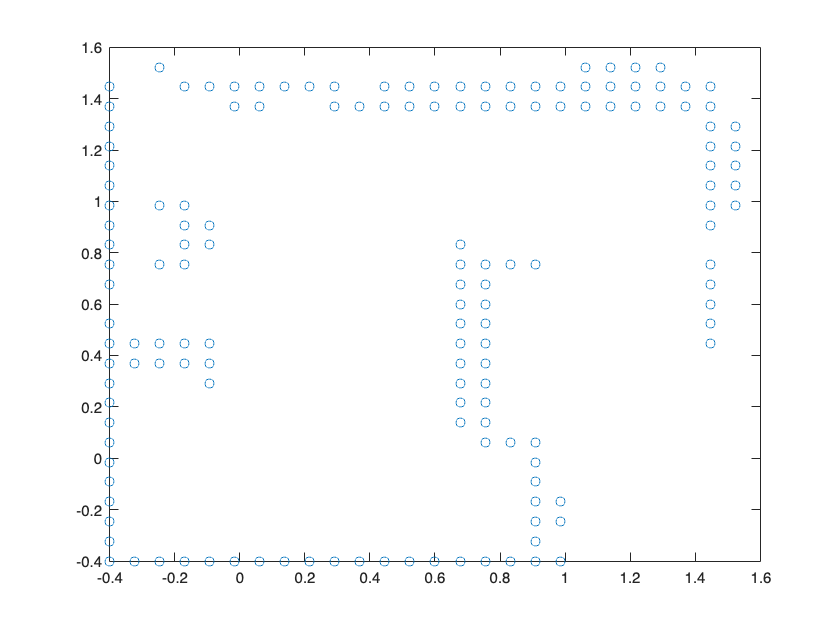

clf;
figure();
plot(new_x, new_y, 'o'); hold on; % Plot generated point

new_y = new_y';
new_x = new_x';
num_iterations = 20000; % Manew_x number of RANSAC iterations
true_rad = .13; % True radius of the generated circle
tolerance = true_rad/5; % Distance tolerance to consider a point an inlier
radius_tolerance = 0.01; % Tolerance for the radius
[best_center_new_x, best_center_new_y, best_computed_radius, best_inlier_count] = ransacForCircle(new_x,new_y,num_iterations, true_rad, tolerance, radius_tolerance)

best_center_new_x = -0.2846

best_center_new_y = 0.8308

best_computed_radius = 0.1387

best_inlier_count = 7

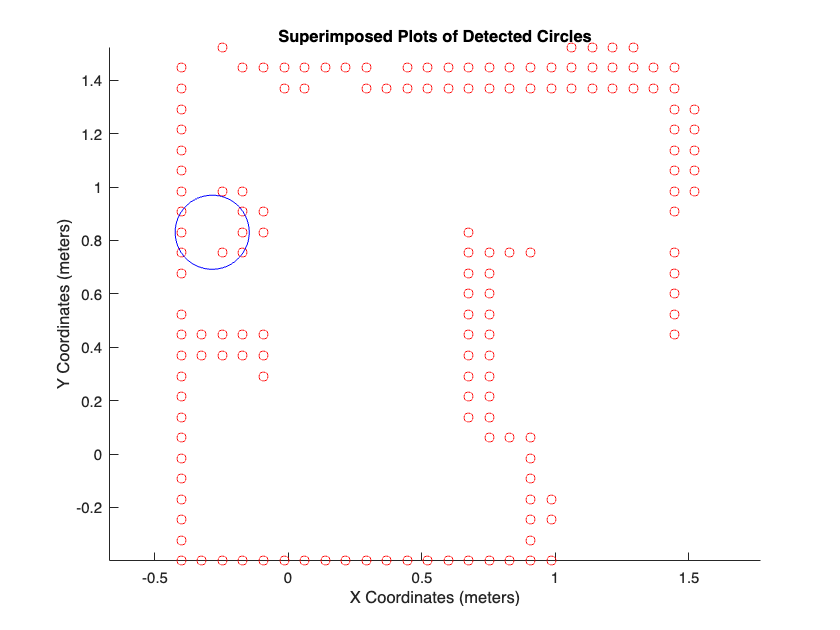


% Initialize the superimposed figure
clf;
figure;
hold on;
axis equal;
title('Superimposed Plots of Detected Circles');

th = 0:pi/50:2*pi;
new_xunit = best_computed_radius * cos(th) + best_center_new_x;
new_yunit = best_computed_radius * sin(th) + best_center_new_y;
plot(new_x, new_y, 'ro'); hold on; % Plot generated points
plot(new_xunit, new_yunit, 'b-'); % Plot best fit circle

xlabel('X Coordinates (meters)');
ylabel('Y Coordinates (meters)');

axis equal;
hold off;

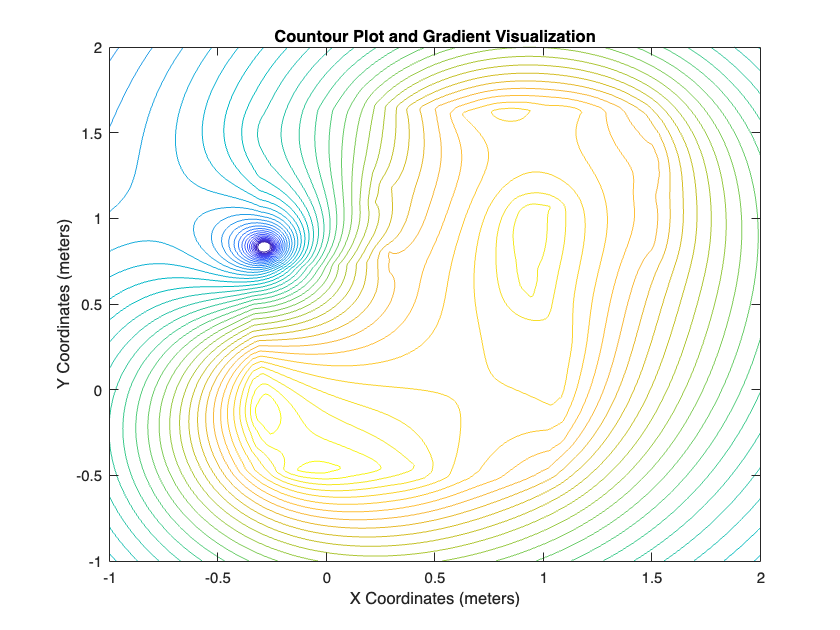

a = old_x;
b = old_y;

[x,y] = meshgrid(-1:0.01:2,-1:0.01:2);
v = 0;
for i = 1:length(a)
    dist = sqrt((a(i) - best_center_new_x)^2 + (b(i) - best_center_new_y)^2);
    if dist > true_rad
        v = v -  log(sqrt((x - a(i)).^2 + (y - b(i)).^2));
    end
end

for theta = 0:0.1:2*pi
    a_circle = (true_rad-0.1) * cos(theta) + best_center_new_x;
    b_circle = (true_rad-0.1) * sin(theta) + best_center_new_y;
     v = v + 5 * log(sqrt((x - a_circle).^2 + (y - b_circle).^2));
end

% Calculate gradient
[U, V] = gradient(v, 0.01, 0.01);  

% Visualize the potential field and its gradient
figure;
contour(x, y, v, 40);  % Increased number of contour levels for better visibility
xlabel('X Coordinates (meters)');
ylabel('Y Coordinates (meters)');
title('Countour Plot and Gradient Visualization');

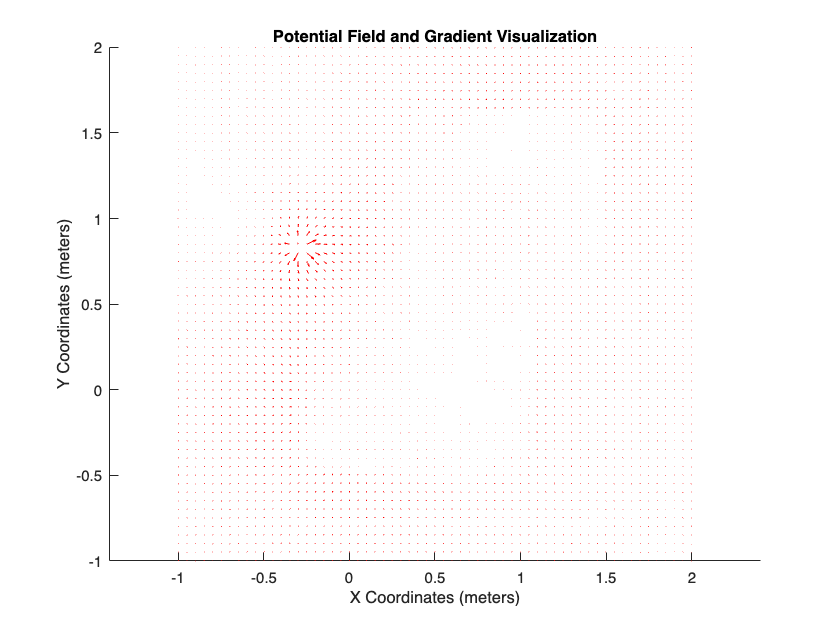


clf;
hold on;
quiver(x(1:5:end, 1:5:end), y(1:5:end, 1:5:end), U(1:5:end, 1:5:end), V(1:5:end, 1:5:end), 'r');
hold off;
axis equal;
title('Potential Field and Gradient Visualization');
xlabel('X Coordinates (meters)');
ylabel('Y Coordinates (meters)');

Deleting previous Neato connection.
Connecting to the Neato.


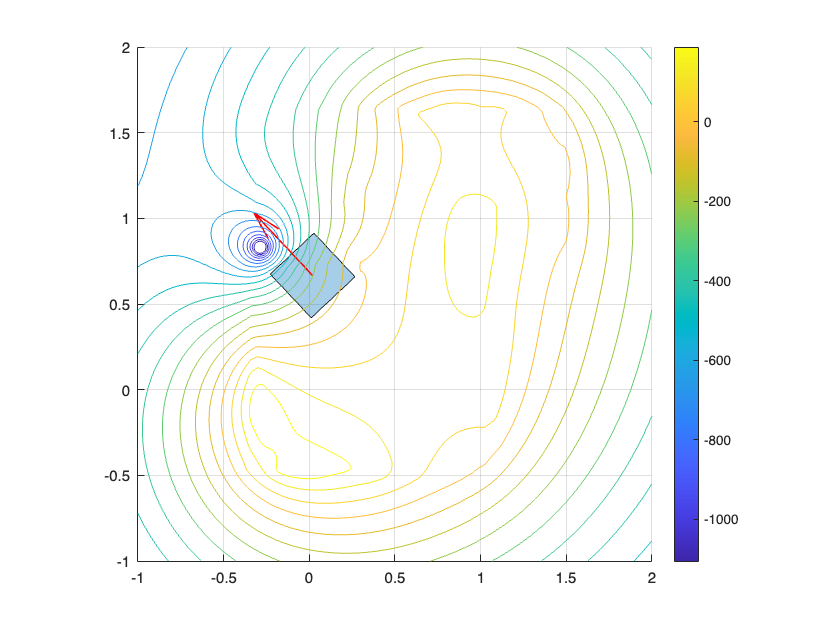

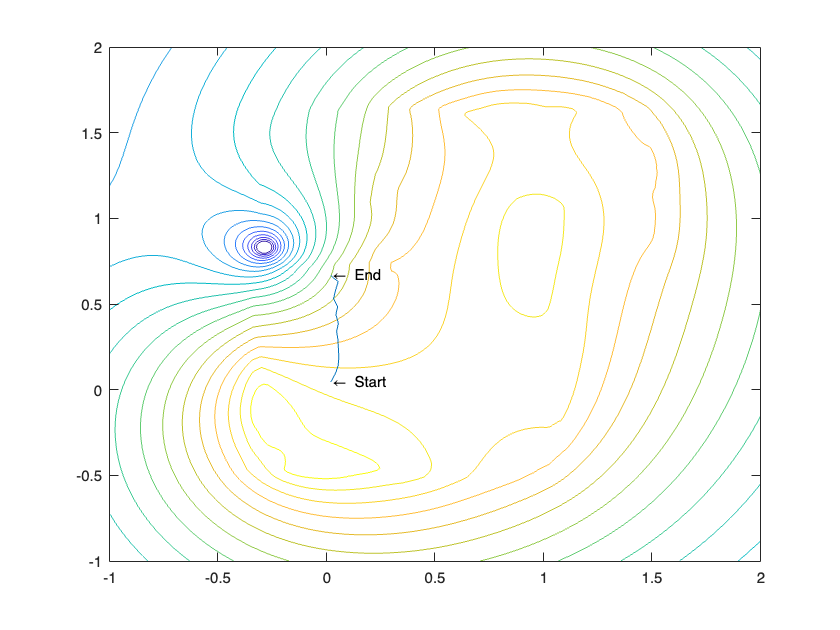

use_sim = true; 
position = [0; 0]; 
heading = [0; 0];
gradient_ascent(use_sim, position, heading, x,y, v, U, V)

function [x, y, rs, thetas] = makeCircle(r, anglemin, anglemax, noiseLevel)
    thetas = linspace(anglemin, anglemax, (anglemax-anglemin+1))';
    rs = r*ones(size(thetas));
    rs = rs + randn(size(rs))*noiseLevel;
    x = cosd(thetas).*rs;
    y = sind(thetas).*rs;
end

function isCollinear = checkCollinearity(p1, p2, p3)
    area = abs(det([1, p1; 1, p2; 1, p3])) / 2;
    isCollinear = (area < 1e-4);
end

function [best_center_x, best_center_y, best_computed_radius, best_inlier_count] = ransacForCircle(x, y, num_iterations, true_rad, tolerance, radius_tolerance)
    best_inlier_count = 0;
    best_center_x = 0;
    best_center_y = 0;
    best_computed_radius = 0;

    for k = 1:num_iterations
        % Randomly select 3 unique points
        indices = randperm(length(x), 3);
        pts = [x(indices), y(indices)];

        % Check for collinearity
        if checkCollinearity(pts(1,:), pts(2,:), pts(3,:))
            continue; % Skip this iteration if points are collinear
        end

        A = [2*pts(:,1), 2*pts(:,2), -ones(3, 1)];
        b = pts(:,1).^2 + pts(:,2).^2;

        % Solve for circle parameters
        w = A \ b;
        center_x = w(1);
        center_y = w(2);
        computed_radius = sqrt(center_x^2 + center_y^2 - w(3)); % Correct sign based on your setup

        % Count inliers
        inliers_count = 0;
        for j = 1:length(x)
            dist = norm([center_x; center_y] - [x(j); y(j)]);
            if abs(dist - computed_radius) < tolerance
                inliers_count = inliers_count + 1;
            end
        end

        % Update best model if current model has more inliers and meets radius criteria
        if inliers_count > best_inlier_count && ...
           computed_radius > true_rad - radius_tolerance && ...
           computed_radius < true_rad + radius_tolerance
            best_inlier_count = inliers_count;
            best_center_x = center_x;
            best_center_y = center_y;
            best_computed_radius = computed_radius;
        end
    end
end